clear

x_arr = 0:10:50;
% x_arr = [0 40 50];
load Workspace\state_thres_rho=50.mat;

## Run other scripts

for j = 1:length(x_arr)
rho = x_arr(j);

Parameters;

Model_Atmospheric_turbulence;

% Model_Channel_state_thes;

## Compute AVR Power for Non-adaptive Scheme

        **1.    Non-Adaptive Scheme with M = 16**

%     M = 16;
% 
%     Model_Non_adaptive;
% 
%     P_t_NA_16(j) = P_t;
%     
%     EE_NA_16(j) = EE_anal;

         **2.    Non-Adaptive Scheme with M = 32**

%     M = 32;
% 
%     Model_Non_adaptive;
% 
%     P_t_NA_32(j) = P_t;
%     
%     EE_NA_32(j) = EE_anal;

         **3.    Non-Adaptive Scheme with M = 64**

%     M = 64;
% 
%     Model_Non_adaptive;
% 
%     P_t_NA_64(j) = P_t;
%     
%     EE_NA_64(j) = EE_anal;

## Compute AVR Power for AM Scheme

    Model_AM;

P_t = 2.8224

EE_anal = 3.5431e+08

P_t = 2.8984

EE_anal = 3.4502e+08

P_t = 3.1386

EE_anal = 3.1862e+08

P_t = 3.5827

EE_anal = 2.7912e+08

P_t = 4.3100

EE_anal = 2.3202e+08

P_t = 5.4639

EE_anal = 1.8302e+08


    P_t_AM(j) = P_t;
    
    EE_AM(j) = EE_anal;

    if (P_t > P_t_min)
        Model_AM_sim;

        P_t_AM_sim(j) = P_t;

        rate_AM_sim(j) = rate_sim;
        
        EE_AM_sim(j) = EE_sim; 
    end

rate_sim = 999735250

EE_sim = 3.5429e+08

rate_sim = 1.0000e+09

EE_sim = 3.4509e+08

rate_sim = 1.0002e+09

EE_sim = 3.1873e+08

rate_sim = 999829500

EE_sim = 2.7913e+08

rate_sim = 999669750

EE_sim = 2.3199e+08

rate_sim = 999230500

EE_sim = 1.8291e+08

## Compute AVR Power for AMP Scheme

- Optimal AMP

    Model_AMP;

P_t = 2.3055

EE_anal = 4.3375e+08

P_t = 2.3634

EE_anal = 4.2312e+08

P_t = 2.5484

EE_anal = 3.9241e+08

P_t = 2.8937

EE_anal = 3.4559e+08

P_t = 3.4622

EE_anal = 2.8883e+08

P_t = 4.3664

EE_anal = 2.2902e+08


    P_t_AMP(j) = P_t;
    
    EE_AMP(j) = EE_anal;

    Model_AMP_sim;

rate_sim = 1.0006e+09

P_t_sim = 2.3065

EE_sim = 4.3391e+08

rate_sim = 1.0002e+09

P_t_sim = 2.3628

EE_sim = 4.2340e+08

rate_sim = 998729250

P_t_sim = 2.5411

EE_sim = 3.9311e+08

rate_sim = 998552250

P_t_sim = 2.8707

EE_sim = 3.4791e+08

rate_sim = 997207500

P_t_sim = 3.4103

EE_sim = 2.9246e+08

rate_sim = 998725000

P_t_sim = 4.2724

EE_sim = 2.3380e+08


    P_t_AMP_sim(j) = P_t_sim;

    rate_AMP_sim(j) = rate_sim;
    
    EE_AMP_sim(j) = EE_sim;

-         Suboptimal AMP (transmit power is fixed for each channel state)

    Model_Channel_state_assignment;
    
    Model_AMP_subopt_state;

P_t = 2.4445

rate_anal = 1.0200e+09

EE_anal = 4.1726e+08

P_t = 2.5023

rate_anal = 1.0181e+09

EE_anal = 4.0687e+08

P_t = 2.6901

rate_anal = 1.0140e+09

EE_anal = 3.7695e+08

P_t = 3.0488

rate_anal = 1.0112e+09

EE_anal = 3.3167e+08

P_t = 3.6553

rate_anal = 1.0138e+09

EE_anal = 2.7735e+08

P_t = 4.5002

rate_anal = 1.0044e+09

EE_anal = 2.2319e+08


    P_t_AMP_subopt(j) = P_t;

    rate_AMP_subopt(j) = rate_anal;
    
    EE_AMP_subopt(j) = EE_anal;
    
    Model_AMP_subopt_state_sim;

EE_sim = 4.1755e+08

EE_sim = 4.0684e+08

EE_sim = 3.7713e+08

EE_sim = 3.3167e+08

EE_sim = 2.7794e+08

EE_sim = 2.2598e+08

    
    P_t_AMP_subopt_sim(j) = P_t_sim;

    rate_AMP_subopt_sim(j) = rate_sim;
    
    EE_AMP_subopt_sim(j) = EE_sim;

end

## Plot figures: AVR transmitted power vs. requested rate

- AM Scheme

P_t_AM_dbm = 10*log10(P_t_AM) + 30;

plot(x_arr, P_t_AM_dbm, "DisplayName", 'AM Scheme', 'LineWidth', 2)
hold on

P_t_AM_dbm_sim = 10*log10(P_t_AM_sim) + 30;

plot(x_arr, P_t_AM_dbm_sim, 'r.', 'HandleVisibility','off', 'MarkerSize', 15)

- AMP Scheme

P_t_AMP_dbm = 10*log10(P_t_AMP) + 30;

plot(x_arr, P_t_AMP_dbm, "DisplayName", 'AMP Scheme', 'LineWidth', 2)

P_t_AMP_dbm_sim = 10*log10(P_t_AMP_sim) + 30;

plot(x_arr, P_t_AMP_dbm_sim, 'r.', 'HandleVisibility','off', 'MarkerSize', 15)

- Sub-optimal AMP Scheme (state)

P_t_AMP_subopt_dbm = 10*log10(P_t_AMP_subopt) + 30;

plot(x_arr, P_t_AMP_subopt_dbm, "DisplayName", 'sub-optimal AMP Scheme (State)', 'LineWidth', 2)

P_t_AMP_subopt_dbm_sim = 10*log10(P_t_AMP_subopt_sim) + 30;

plot(x_arr, P_t_AMP_subopt_dbm_sim, 'r.', "DisplayName", 'Simulation', 'MarkerSize', 15)

- Non-adaptive Scheme

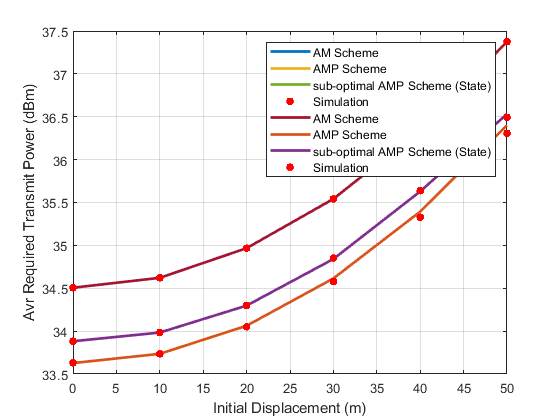

% P_t_NA_16_dbm = 10*log10(P_t_NA_16) + 30;
% P_t_NA_32_dbm = 10*log10(P_t_NA_32) + 30;
% P_t_NA_64_dbm = 10*log10(P_t_NA_64) + 30;
% 
% plot(x_arr, P_t_NA_16_dbm, "DisplayName", 'Non-adaptive Scheme, M = 16', 'LineWidth', 2)

% plot(x_arr, P_t_NA_32_dbm, "DisplayName", 'Non-adaptive Scheme, M = 32', 'LineWidth', 2)

% plot(x_arr, P_t_NA_64_dbm, "DisplayName", 'Non-adaptive Scheme, M = 64', 'LineWidth', 2)
hold off

xlabel('Initial Displacement (m)')
ylabel('Avr Required Transmit Power (dBm)')
legend()
grid on

## Figure: EE vs. avr transmitted power

- AM Scheme

semilogy(x_arr, EE_AM, '-black', "DisplayName", 'AM Scheme', 'LineWidth', 3)
hold on

semilogy(x_arr, EE_AM_sim, 'r.', 'HandleVisibility','off', 'MarkerSize', 25)

- AMP Scheme

semilogy(x_arr, EE_AMP,'-.black', "DisplayName", 'AMP Scheme', 'LineWidth', 3)

semilogy(x_arr, EE_AMP_sim, 'r.', 'HandleVisibility','off', 'MarkerSize', 25)

- Sub-optimal AMP Scheme (state)

semilogy(x_arr, EE_AMP_subopt,':black', "DisplayName", 'SAMP Scheme', 'LineWidth', 3)

semilogy(x_arr, EE_AMP_subopt_sim, 'r.', "DisplayName", 'Simulation', 'MarkerSize', 25)

- Non-adaptive Scheme

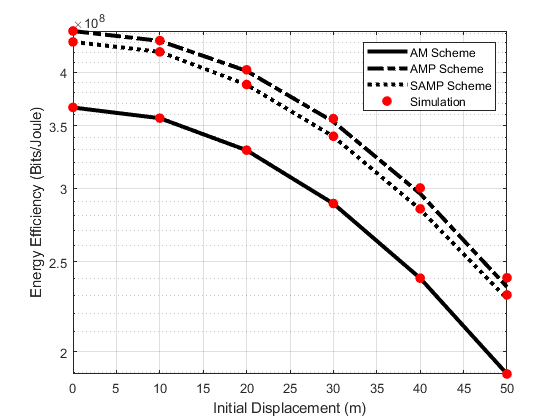

% semilogy(x_arr, EE_NA_16, "DisplayName", 'Non-adaptive Scheme, M = 16', 'LineWidth', 3)

% semilogy(x_arr, EE_NA_32, "DisplayName", 'Non-adaptive Scheme, M = 32', 'LineWidth', 2)

% semilogy(x_arr, EE_NA_64, "DisplayName", 'Non-adaptive Scheme, M = 64', 'LineWidth', 2)

hold off
xlabel('Initial Displacement (m)')
ylabel('Energy Efficiency (Bits/Joule)')
legend()
grid on